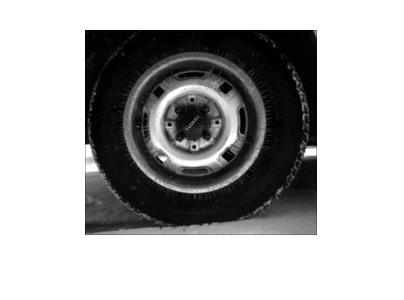

inputImg = imread('tire.tif');
outputImg = imread('cameraman.tif');
imshow(inputImg);

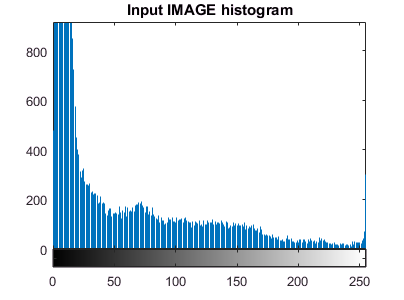

imhist(inputImg);
title('Input IMAGE histogram');

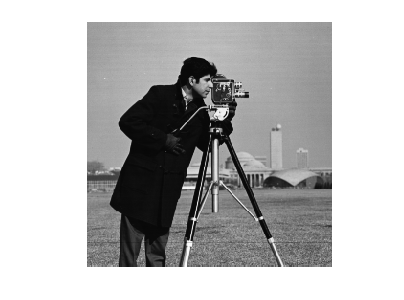

imshow(outputImg);

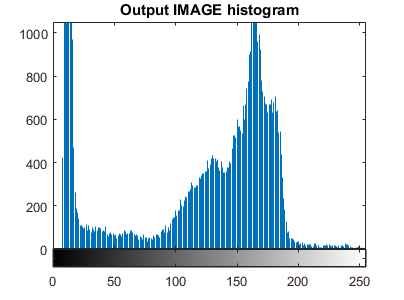

imhist(outputImg);
title('Output IMAGE histogram');

[lengthI,breadthI] = size(inputImg);
[lengthO,breadthO] = size(outputImg);

countI = zeros(1,256);
countO = zeros(1,256);

for i = 1 : lengthI
    for j = 1:breadthI
        countI(1,inputImg(i,j)+1) = countI(1,inputImg(i,j)+1)+1;
    end
end

for i = 1 : lengthO
    for j = 1:breadthO
        countO(1,outputImg(i,j)+1) = countO(1,outputImg(i,j)+1)+1;
    end
end

totalInPixels = lengthI*breadthI;
inpixProb = countI/totalInPixels;
incumFreq = zeros(1,256);
incumFreq(1,1) = inpixProb(1,1);
for i = 2:256
    incumFreq(1,i) = incumFreq(1,i-1) + inpixProb(1,i);
end
incumMapping = floor(255*incumFreq);

totaloutPixels = lengthO*breadthO;
outpixProb = countO/totaloutPixels;
outcumFreq = zeros(1,256);
outcumFreq(1,1) = outpixProb(1,1);
for i = 2:256
    outcumFreq(1,i) = outcumFreq(1,i-1) + outpixProb(1,i);
end
outcumMapping = floor(255*outcumFreq);

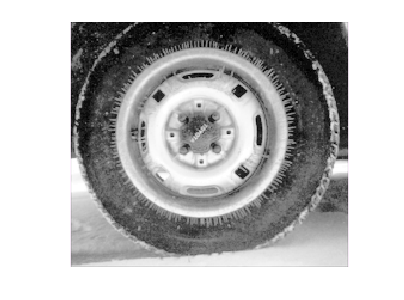

inImgMap = uint8(zeros(lengthI,breadthI));
for i = 1 : lengthI
    for j = 1:breadthI
        inImgMap(i,j) = floor(incumMapping(1,inputImg(i,j)+1));
    end
end
imshow(inImgMap);

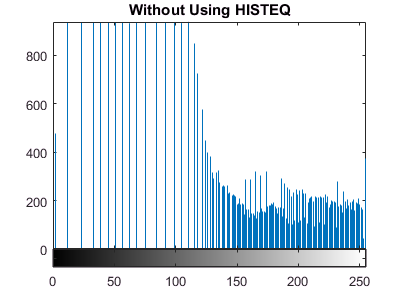

imhist(inImgMap);
title('Without Using HISTEQ');

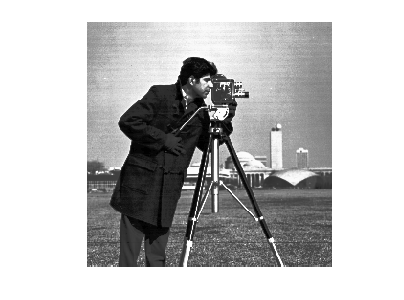

outImgMap = uint8(zeros(lengthO,breadthO));
for i = 1 : lengthO
    for j = 1:breadthO
        outImgMap(i,j) = floor(outcumMapping(1,outputImg(i,j)+1));
    end
end
imshow(outImgMap);

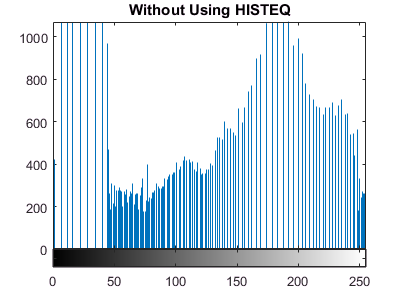

imhist(outImgMap);
title('Without Using HISTEQ');

finalMap = zeros(1,256);
for i=1:256
    count = 1;
    while incumMapping(1,i)>outcumMapping(1,count)
        count = count+1;
        if count == 256
            break;
        end
    end
    finalMap(1,i) = count;
end

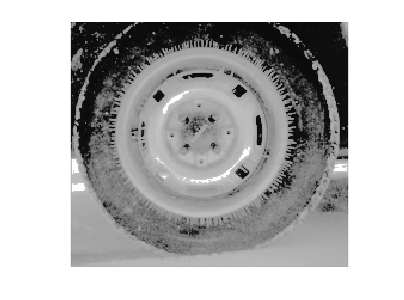

output = uint8(zeros(lengthI,breadthI));
for i = 1 : lengthI
    for j = 1:breadthI
        output(i,j) = finalMap(1,inputImg(i,j)+1);
    end
end
imshow(output);

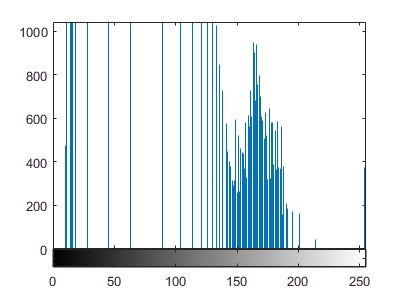

imhist(output);

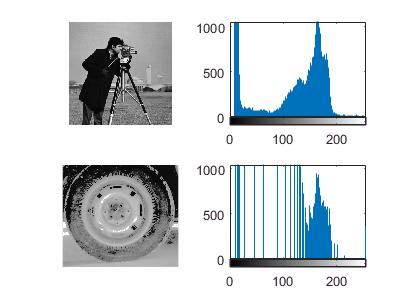

subplot(2,2,1);
imshow(outputImg);

subplot(2,2,2);
imhist(outputImg);

subplot(2,2,3);
imshow(output);

subplot(2,2,4);
imhist(output);